% Test with CSV data

y = csvread("test_data/y.csv");
w = csvread("test_data/w.csv");
X = csvread("test_data/X.csv");

size(y)

ans =          100       20000


norm_X = normc(X);
gramian_X = norm_X'*norm_X;

% norm_y = normc(y);


% Skip header
tic
for y_index = 1:length(y)
    curr_y = y(:,y_index);
    norm_y = normc(curr_y);
    x = ForErrorProposedv0(norm_y, norm_X, gramian_X, norm_X'*norm_y, 17, 0.00000001);
end
toc

Elapsed time is 26.691379 seconds.


tic
for y_index = 1:length(y)
    curr_y = y(:,y_index);
%     norm_y = normc(curr_y);
%     x = OMP(norm_y, norm_X, gramian_X, norm_X'*norm_y, 500, 0.02);
    x = OMP(curr_y, X, 17);
end
toc

Elapsed time is 116.256716 seconds.


load("CroppedYale_96_84_2414_subset.mat")

% Remove dimension of length 1
img1 = squeeze(faces(1,:,:));
disp("Showing first image in Yale")

Showing first image in Yale


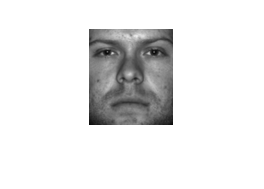

imshow(img1)

num_images = length(facecls)

num_images = 2414

% Uniform sampling images to form training set
perms = randperm(num_images);
% Split train and test 50-50
% Sort them to make it easier for us to plot. Has no effect on
% classification
training_set_indexes = sort(perms(1:num_images/2))

training_set_indexes =      3     6     7    11    14    16    17    22    28    30    32    33    34    35    38    40    41    42    45    46    47    51    54    55    56    58    60    62    63    68    69    70    72    74    76    77    78    80    81    86    89    91    92    96    98    99   100   101   103   105


test_set_indexes = sort(perms((num_images/2) + 1:end))

test_set_indexes =      1     2     4     5     8     9    10    12    13    15    18    19    20    21    23    24    25    26    27    29    31    36    37    39    43    44    48    49    50    52    53    57    59    61    64    65    66    67    71    73    75    79    82    83    84    85    87    88    90    93


training_set = faces(training_set_indexes,:,:);
labels_for_training_set = facecls(training_set_indexes);

disp("Show first image in training set to see its working fine");

Show first image in training set to see its working fine


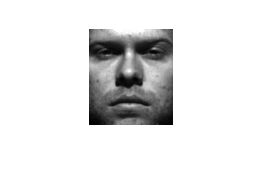

imshow(squeeze(training_set(1,:,:)))

% We need to flatten images to a single column
height = 96

height = 96

width = 84

width = 84

col_img=reshape(squeeze(training_set(1,:,:)),height*width,1)'

col_img = 1×8064 uint8 row vector
    62    70    76    85    93    90    93    96    88    65    52    59    65    72    62    50    37    21    17    20    23    25    30    37    46    54    66    91   114   130   139   144   154   163   176   185   186   185   175   166   163   155   144   132   124   110    92    95    97    89


% Forming giant A

%double(imresize(Test_Image,[m1 n1]))
A = [];
for i=1:length(training_set)
    col_img=reshape(squeeze(training_set(i,:,:)),height*width,1);
    col_img = double(col_img);
    A = [A col_img];
end
disp("Size of A")

Size of A


size(A)

ans =         8064        1207


% % Run algorithm for just 1 test image
% disp("For now, test with the 200th test_set example")

For now, test with the 200th test_set example


% test_img_1 = squeeze(faces(test_set_indexes(200),:,:));
% disp("Test image")

Test image


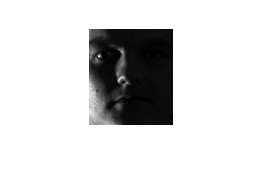

% imshow(test_img_1)

% flat_test_img_1 = reshape(test_img_1,height*width,1);
% flat_test_img_1 = double(flat_test_img_1);
% 
% % x = OMP(flat_test_img_1, A, 30);
% norm_A = normc(A);
% x = ForErrorProposedv0(normc(flat_test_img_1), norm_A, norm_A'*norm_A, norm_A'*normc(flat_test_img_1), 2000, 0.001);
% 
% residual_for_class = [];
% for class = 1:38
%     residual_for_class = [residual_for_class norm(normc(flat_test_img_1) - norm_A(:, labels_for_training_set' == class) * x(labels_for_training_set' == class),2)];
% end
% disp("Residual plot for first test image")

Residual plot for first test image


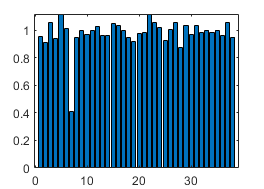

% bar(residual_for_class)

% [resid cls_pick] = min(residual_for_class);
% disp("Predicted image class: " + cls_pick);

Predicted image class: 7


% disp("True image class")

True image class


% facecls(test_set_indexes(1))

ans = 1

disp("Squeeze all images into columns. make them nice and ready to just apply OMP!")

Squeeze all images into columns. make them nice and ready to just apply OMP!



% Preallocate
reshaped_test_images = zeros(size(A));
for t=1:length(test_set_indexes)
    curr_img = squeeze(faces(test_set_indexes(t),:,:));
    reshaped_test_images(:,t) = double(reshape(curr_img,height*width,1));
end
% Test the above works correctly
imshow(reshape(uint8(reshaped_test_images(:,1)), [height width]))

disp("OMP using our naive algorithm from HW5")

OMP using our naive algorithm from HW5


% Testing with full images in A. No random projections, no
% scaling/downsapling!
classif_accu = [];
% Why doesn't this need S level??
% S = 30;

% images_to_try = length(test_set_indexes);
images_to_try = 100;

% Cant figure out a way to just print this to console
% profile on
tic

for t=1:images_to_try
    x = OMP(reshaped_test_images(:,t), A, S);
%     x = ForErrorProposedv0(norm_y, norm_A, norm_A'*norm_A, norm_A'*norm_y, 1500, 0.02);
    
    % Calculate residuals for each class. Pick lowest (unless above a
    % certain threshold)
    residual_for_class = [];
    for class = 1:38
        residual_for_class = [residual_for_class norm(reshaped_test_images(:,t) - A(:, labels_for_training_set' == class) * x(labels_for_training_set' == class),2)];
    end
    
    [resid cls_pick] = min(residual_for_class);
    % If min residual is very high, then the image most probably hasn't been seen before!
%     if resid > 6000
%         cls_pick = -1;
%     end
    true_class = facecls(test_set_indexes(t));
    classif_accu = [classif_accu; cls_pick, true_class];
end

correct_preds = 0;
for a=1:length(classif_accu)
    if classif_accu(a,1) == classif_accu(a,2)
        correct_preds = correct_preds + 1;
    end
end
disp("OMP - S="+S+", full dict. A. Number of correct predictions: "+ correct_preds +" / " + images_to_try)

OMP - S=30, full dict. A. Number of correct predictions: 96 / 100



toc

Elapsed time is 44.892583 seconds.


% ForErrorProposedv0

% Testing with full images in A. No random projections, no
% scaling/downsapling!
classif_accu = [];
% Why doesn't this need S level??
% S = 30;

% Simple OMP doesnt need the steps below, so here we count their execution time too!
tic

norm_A = normc(A);
gramian_A = norm_A'*norm_A;

% images_to_try = length(test_set_indexes);
images_to_try = 100;

% Cant figure out a way to just print this to console
% profile on


for t=1:images_to_try
    y = reshaped_test_images(:,t);
    norm_y = normc(y);
    % I did the same for Y
    % Linear regression! Very slow!
    %x = A \ y;

%     Adjusting the allowed residue improves accuracy a lot without much
%     performance penalty!
    x = ForErrorProposedv0(norm_y, norm_A, gramian_A, norm_A'*norm_y, 500, 0.02);
    
    % Calculate residuals for each class. Pick lowest (unless above a
    % certain threshold)
    residual_for_class = [];
    for class = 1:38
        residual_for_class = [residual_for_class norm(norm_y - norm_A(:, labels_for_training_set' == class) * x(labels_for_training_set' == class),2)];
    end
    
    [resid cls_pick] = min(residual_for_class);
    % If min residual is very high, then the image most probably hasn't been seen before!
%     if resid > 6000
%         cls_pick = -1;
%     end
    true_class = facecls(test_set_indexes(t));
    classif_accu = [classif_accu; cls_pick, true_class];
end

correct_preds = 0;
for a=1:length(classif_accu)
    if classif_accu(a,1) == classif_accu(a,2)
        correct_preds = correct_preds + 1;
    end
end
disp("OMP using efficient ForErrorProposedv0")

OMP using efficient ForErrorProposedv0


disp("OMP - full dict. A. Number of correct predictions: "+ correct_preds +" / " + images_to_try)

OMP - full dict. A. Number of correct predictions: 100 / 100



toc

Elapsed time is 13.514496 seconds.


% profile viewer
% profile off

% ForErrorProposedv1

% Testing with full images in A. No random projections, no
% scaling/downsapling!
classif_accu = [];
% Why doesn't this need S level??
% S = 30;

% Simple OMP doesnt need the steps below, so here we count their execution time too!
tic

norm_A = normc(A);
gramian_A = norm_A'*norm_A;

% images_to_try = length(test_set_indexes);
images_to_try = 100;

% Cant figure out a way to just print this to console
% profile on

for t=1:images_to_try
    y = reshaped_test_images(:,t);
    norm_y = normc(y);
    % I did the same for Y
    % Linear regression! Very slow!
    %x = A \ y;
%     x = OMP(flat_test_img_1, A, S);
    x = ForErrorProposedv1(norm_y, norm_A, gramian_A, norm_A'*norm_y, 500, 0.02);
    
    % Calculate residuals for each class. Pick lowest (unless above a
    % certain threshold)
    residual_for_class = [];
    for class = 1:38
        residual_for_class = [residual_for_class norm(norm_y - norm_A(:, labels_for_training_set' == class) * x(labels_for_training_set' == class),2)];
    end
    
    [resid cls_pick] = min(residual_for_class);
    % If min residual is very high, then the image most probably hasn't been seen before!
%     if resid > 6000
%         cls_pick = -1;
%     end
    true_class = facecls(test_set_indexes(t));
    classif_accu = [classif_accu; cls_pick, true_class];
end

correct_preds = 0;
for a=1:length(classif_accu)
    if classif_accu(a,1) == classif_accu(a,2)
        correct_preds = correct_preds + 1;
    end
end
disp("OMP using efficient ForErrorProposedv1")

OMP using efficient ForErrorProposedv1


disp("OMP - full dict. A. Number of correct predictions: "+ correct_preds +" / " + images_to_try)

OMP - full dict. A. Number of correct predictions: 100 / 100



toc

Elapsed time is 18.811541 seconds.


% ForErrorProposedv2

% Testing with full images in A. No random projections, no
% scaling/downsapling!
classif_accu = [];
% Why doesn't this need S level??
% S = 30;
norm_A = normc(A);
gramian_A = norm_A'*norm_A;

% images_to_try = length(test_set_indexes);
images_to_try = 100;

% Cant figure out a way to just print this to console
% profile on
tic

for t=1:images_to_try
    % This is my 'Y'
    y = reshaped_test_images(:,t);
    norm_y = normc(y);
    % I did the same for Y
    % Linear regression! Very slow!
    %x = A \ y;
%     x = OMP(flat_test_img_1, A, S);
    x = ForErrorProposedv2(norm_y, norm_A, gramian_A, norm_A'*norm_y, 500, 0.02);
    
    % Calculate residuals for each class. Pick lowest (unless above a
    % certain threshold)
    residual_for_class = [];
    for class = 1:38
        residual_for_class = [residual_for_class norm(norm_y - norm_A(:, labels_for_training_set' == class) * x(labels_for_training_set' == class),2)];
    end
    
    [resid cls_pick] = min(residual_for_class);
    % If min residual is very high, then the image most probably hasn't been seen before!
%     if resid > 6000
%         cls_pick = -1;
%     end
    true_class = facecls(test_set_indexes(t));
    classif_accu = [classif_accu; cls_pick, true_class];
end

correct_preds = 0;
for a=1:length(classif_accu)
    if classif_accu(a,1) == classif_accu(a,2)
        correct_preds = correct_preds + 1;
    end
end
disp("OMP using efficient ForErrorProposedv2")

OMP using efficient ForErrorProposedv2


disp("OMP - full dict. A. Number of correct predictions: "+ correct_preds +" / " + images_to_try)

OMP - full dict. A. Number of correct predictions: 100 / 100



toc

Elapsed time is 63.321608 seconds.


% ForErrorProposedv3

% Testing with full images in A. No random projections, no
% scaling/downsapling!
classif_accu = [];
% Why doesn't this need S level??
% S = 30;
norm_A = normc(A);
gramian_A = norm_A'*norm_A;

% images_to_try = length(test_set_indexes);
images_to_try = 100;

% Cant figure out a way to just print this to console
% profile on
tic

for t=1:images_to_try
    y = reshaped_test_images(:,t);
    norm_y = normc(y);
    % I did the same for Y
    % Linear regression! Very slow!
    %x = A \ y;
%     x = OMP(flat_test_img_1, A, S);
    x = ForErrorProposedv3(norm_y, norm_A, gramian_A, norm_A'*norm_y, 500, 0.02);
    
    % Calculate residuals for each class. Pick lowest (unless above a
    % certain threshold)
    residual_for_class = [];
    for class = 1:38
        residual_for_class = [residual_for_class norm(norm_y - norm_A(:, labels_for_training_set' == class) * x(labels_for_training_set' == class),2)];
    end
    
    [resid cls_pick] = min(residual_for_class);
    % If min residual is very high, then the image most probably hasn't been seen before!
%     if resid > 6000
%         cls_pick = -1;
%     end
    true_class = facecls(test_set_indexes(t));
    classif_accu = [classif_accu; cls_pick, true_class];
end

correct_preds = 0;
for a=1:length(classif_accu)
    if classif_accu(a,1) == classif_accu(a,2)
        correct_preds = correct_preds + 1;
    end
end
disp("OMP using efficient ForErrorProposedv3")

OMP using efficient ForErrorProposedv3


disp("OMP - full dict. A. Number of correct predictions: "+ correct_preds +" / " + images_to_try)

OMP - full dict. A. Number of correct predictions: 100 / 100



toc

Elapsed time is 87.201770 seconds.


% ForErrorProposedv4

OMP using efficient ForErrorProposedv0


% Testing with full images in A. No random projections, no
% scaling/downsapling!
classif_accu = [];
% Why doesn't this need S level??
% S = 30;

% tic up here. Simple OMP doesn't need these, so its unfair to not count
% their computation time now!
tic
norm_A = normc(A);
gramian_A = norm_A'*norm_A;

% images_to_try = length(test_set_indexes);
images_to_try = 100;

% Cant figure out a way to just print this to console
% profile on

for t=1:images_to_try
    test_img = squeeze(faces(test_set_indexes(t),:,:));
    % This is my 'Y'
    y = reshape(test_img,height*width,1);
    y = double(y);
    norm_y = normc(y);
    % I did the same for Y
    % Linear regression! Very slow!
    %x = A \ y;
%     x = OMP(flat_test_img_1, A, S);
    x = ForErrorProposedv4(norm_y, norm_A, gramian_A, norm_A'*norm_y, 500, 0.02);
    
    % Calculate residuals for each class. Pick lowest (unless above a
    % certain threshold)
    residual_for_class = [];
    for class = 1:38
        residual_for_class = [residual_for_class norm(norm_y - norm_A(:, labels_for_training_set' == class) * x(labels_for_training_set' == class),2)];
    end
    
    [resid cls_pick] = min(residual_for_class);
    % If min residual is very high, then the image most probably hasn't been seen before!
%     if resid > 6000
%         cls_pick = -1;
%     end
    true_class = facecls(test_set_indexes(t));
    classif_accu = [classif_accu; cls_pick, true_class];
end

Index in position 2 is invalid. Array indices must be positive integers or logical values.

Error in HW7>ForErrorProposedv4 (line 1068)
projections = projections -dict.'*(dict(:,gamma)*(F(1,1)*a_F(1)));


correct_preds = 0;
for a=1:length(classif_accu)
    if classif_accu(a,1) == classif_accu(a,2)
        correct_preds = correct_preds + 1;
    end
end
disp("OMP using efficient ForErrorProposedv4")
disp("OMP - full dict. A. Number of correct predictions: "+ correct_preds +" / " + images_to_try)

toc

% Downsampling with different scaling factors!
disp("Using random projections to downsize images! A=orth(A')'")
scaling_factors = [9, 16, 64, 144, 288, 576, 1152]
scaling_accuracies = [];

for scaling_fac = scaling_factors
    random_proj_A = randn(8064 / scaling_fac,8064);
    random_proj_A = orth(random_proj_A')';
    downsamp_A = random_proj_A*A;
    downsamp_A = normc(downsamp_A);
    
    % Testing with images in A downsampled to 896 using Random Projections
    classif_accu = [];
    S = 30;
    
    for t=1:length(test_set_indexes)
        test_img = squeeze(faces(test_set_indexes(t),:,:));
        flat_test_img_1 = reshape(test_img,height*width,1);
        flat_test_img_1 = double(flat_test_img_1);
        % flat_test_img_1 is my Y. Also projecting it
        flat_test_img_1 = random_proj_A*flat_test_img_1;
        flat_test_img_1 = normc(flat_test_img_1);
        % I did the same for Y
        % Linear regression! Very slow!
        %x = A \ y;
    %     x = OMP(flat_test_img_1, A, S);
        x = OMP(flat_test_img_1, downsamp_A, S);
        % Calculate residuals for each class. Pick lowest (unless above a
        % certain threshold)
        residual_for_class = [];
        for class = 1:38
            residual_for_class = [residual_for_class norm(flat_test_img_1 - downsamp_A(:, labels_for_training_set' == class) * x(labels_for_training_set' == class),2)];
        end
        
        [resid cls_pick] = min(residual_for_class);
        % If min residual is very high, then the image most probably hasn't been seen before!
        if resid > 6000
            cls_pick = -1;
        end
        true_class = facecls(test_set_indexes(t));
        classif_accu = [classif_accu; cls_pick, true_class];
    end
    
    correct_preds = 0;
    for a=1:length(classif_accu)
        if classif_accu(a,1) == classif_accu(a,2)
            correct_preds = correct_preds + 1;
        end
    end
    disp("OMP - S="+S+", Random Projections (image size " + 8064 / scaling_fac + ", Scaling factor " + scaling_fac + "!).")
    disp("Number of correct predictions: "+ correct_preds +" / " + length(test_set_indexes))
    scaling_accuracies = [scaling_accuracies correct_preds];
end
scaling_accuracies

plot(scaling_factors, scaling_accuracies)

disp("Test Noise adding:")

Test Noise adding:


clean_img = squeeze(faces(test_set_indexes(2),:,:));
disp("Clean image:")

Clean image:


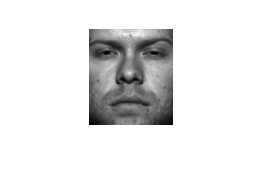

imshow(clean_img)

noise_img = imnoise(clean_img ,'salt & pepper',0.4);
disp("Noisy image:")

Noisy image:


imshow(noise_img)

disp("OMP - Test recovery of first 50 test images with varying levels of noise")

OMP - Test recovery of first 50 test images with varying levels of noise


S = 30;
nr_images_to_test = 50;
noise_percentages = [0 0.01 0.1 .2 0.3 0.4 0.5 0.6 0.7 .8 0.9 1]

noise_percentages =          0    0.0100    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


correct_preds = [];
% Solve using much faster OMP!
for noise_amount = noise_percentages
    classif_accu = [];
    for t=1:nr_images_to_test
        test_img = squeeze(faces(test_set_indexes(t),:,:));
        % Add noise
        test_img = imnoise(test_img ,'salt & pepper',noise_amount);
        flat_test_img_1 = reshape(test_img,height*width,1);
        flat_test_img_1 = double(flat_test_img_1);
        
%         new_A = [A eye(8064)];
        x = OMP(flat_test_img_1, A, S);
        residual_for_class = [];
        for class = 1:38
            residual_for_class = [residual_for_class norm(flat_test_img_1 - A(:, labels_for_training_set' == class) * x(labels_for_training_set' == class),2)];
        end
        [resid cls_pick] = min(residual_for_class);
        % If min residual is very high, then the image most probably isnt in the database!
        % Here we should increase residual threshold because high-noise
        % images will be much more difficult to correctly classify, but we
        % want to try anyway!
%         if resid > 9000
%             cls_pick = -1;
%         end
        true_class = facecls(test_set_indexes(t));
        classif_accu = [classif_accu; cls_pick, true_class];
    end
    %classif_accu
    %classif_accu(1,:) == classif_accu(2,:)
    current_correct_preds = 0;
    for a=1:length(classif_accu)
        if classif_accu(a,1) == classif_accu(a,2)
            current_correct_preds = current_correct_preds + 1;
        end
    end
    disp("OMP - S="+S+", full dict. A. Number of correct predictions / " + nr_images_to_test)
    disp("Noise level: " + noise_amount)
    current_correct_preds
    correct_preds = [correct_preds current_correct_preds];
end

OMP - S=50, full dict. A. Number of correct predictions / 50


Noise level: 0


current_correct_preds = 49

OMP - S=50, full dict. A. Number of correct predictions / 50


Noise level: 0.01


current_correct_preds = 49

OMP - S=50, full dict. A. Number of correct predictions / 50


Noise level: 0.1


current_correct_preds = 49

OMP - S=50, full dict. A. Number of correct predictions / 50


Noise level: 0.2


current_correct_preds = 47

OMP - S=50, full dict. A. Number of correct predictions / 50


Noise level: 0.3


current_correct_preds = 44

OMP - S=50, full dict. A. Number of correct predictions / 50


Noise level: 0.4


current_correct_preds = 42

OMP - S=50, full dict. A. Number of correct predictions / 50


Noise level: 0.5


current_correct_preds = 34

OMP - S=50, full dict. A. Number of correct predictions / 50


Noise level: 0.6


current_correct_preds = 27

OMP - S=50, full dict. A. Number of correct predictions / 50


Noise level: 0.7


current_correct_preds = 17

OMP - S=50, full dict. A. Number of correct predictions / 50


Noise level: 0.8


current_correct_preds = 2

OMP - S=50, full dict. A. Number of correct predictions / 50


Noise level: 0.9


current_correct_preds = 1

OMP - S=50, full dict. A. Number of correct predictions / 50


Noise level: 1


current_correct_preds = 1

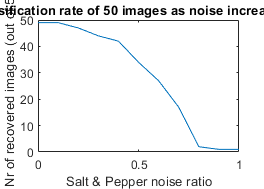

plot(noise_percentages, correct_preds)
xlabel("Salt & Pepper noise ratio")
ylabel("Nr of recovered images (out of 50)")
title("Correct classification rate of 50 images as noise increases using [A I]")
ylim([0,50])

Image with corrupted block example


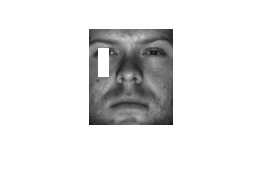

% Make a Block white
% every 84 pixels, make 10 of them white. See example
% Do this for 100 images to test robustness to block corruptions
block_missing_images = [];
for c = test_set_indexes(1:100)
blc_miss = squeeze(faces(c,:,:));
    for i=20:(96/2)
%     if mod(i, 96) == 0
        for j = 10:20
            blc_miss(i,j) = 256;
        end
    end
    if c == test_set_indexes(1)
        disp("Image with corrupted block example")
        imshow(blc_miss)
    end
    block_missing_images = [block_missing_images reshape(blc_miss,height*width,1);];
end


% Testing with full images in A. No random projections, no
% scaling/downsapling!
classif_accu = [];
S = 30;

for t=1:100
%     test_img = squeeze(faces(test_set_indexes(t),:,:));
    % This is my 'Y'
    flat_test_img_1 = block_missing_images(:,t);
    flat_test_img_1 = double(flat_test_img_1);
    % I did the same for Y
    % Linear regression! Very slow!
    %x = A \ y;
    x = OMP(flat_test_img_1, A, S);
    
    % Calculate residuals for each class. Pick lowest (unless above a
    % certain threshold)
    residual_for_class = [];
    for class = 1:38
        residual_for_class = [residual_for_class norm(flat_test_img_1 - A(:, labels_for_training_set' == class) * x(labels_for_training_set' == class),2)];
    end
    
    [resid cls_pick] = min(residual_for_class);
    % If min residual is very high, then the image most probably hasn't been seen before!
    if resid > 6000
        cls_pick = -1;
    end
    true_class = true_class_for_missing_block(t);
    classif_accu = [classif_accu; cls_pick, true_class];
end

correct_preds = 0;
for a=1:length(classif_accu)
    if classif_accu(a,1) == classif_accu(a,2)
        correct_preds = correct_preds + 1;
    end
end
disp("OMP - S="+S+", full dict. A. Number of correct predictions: "+ correct_preds +" / " + 100)

OMP - S=30, full dict. A. Number of correct predictions: 89 / 100


Image with corrupted block example


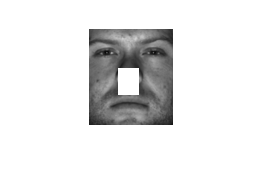

% Make corrupted block bigger
block_missing_images = [];
for c = test_set_indexes(1:100)
blc_miss = squeeze(faces(c,:,:));
    for i=40:96-30
%     if mod(i, 96) == 0
        for j = 30:50
            blc_miss(i,j) = 256;
        end
    end
    if c == test_set_indexes(1)
        disp("Image with corrupted block example")
        imshow(blc_miss)
    end
    block_missing_images = [block_missing_images reshape(blc_miss,height*width,1);];
end


% Testing with full images in A. No random projections, no
% scaling/downsapling!
classif_accu = [];
S = 30;

for t=1:100
%     test_img = squeeze(faces(test_set_indexes(t),:,:));
    % This is my 'Y'
    flat_test_img_1 = block_missing_images(:,t);
    flat_test_img_1 = double(flat_test_img_1);
    % I did the same for Y
    % Linear regression! Very slow!
    %x = A \ y;
    x = OMP(flat_test_img_1, A, S);
    
    % Calculate residuals for each class. Pick lowest (unless above a
    % certain threshold)
    residual_for_class = [];
    for class = 1:38
        residual_for_class = [residual_for_class norm(flat_test_img_1 - A(:, labels_for_training_set' == class) * x(labels_for_training_set' == class),2)];
    end
    
    [resid cls_pick] = min(residual_for_class);
    % If min residual is very high, then the image most probably hasn't been seen before!
    if resid > 9000
        cls_pick = -1;
    end
    true_class = true_class_for_missing_block(t);
    classif_accu = [classif_accu; cls_pick, true_class];
end

correct_preds = 0;
for a=1:length(classif_accu)
    if classif_accu(a,1) == classif_accu(a,2)
        correct_preds = correct_preds + 1;
    end
end
disp("OMP - S="+S+", full dict. A. Number of correct predictions: "+ correct_preds +" / " + 100)

OMP - S=30, full dict. A. Number of correct predictions: 62 / 100


Image with corrupted block example


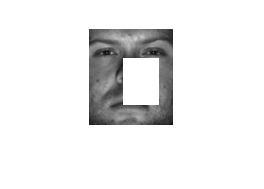

% Make corrupted block bigger
block_missing_images = [];
for c = test_set_indexes(1:100)
blc_miss = squeeze(faces(c,:,:));
    for i=30:96-20
%     if mod(i, 96) == 0
        for j = 35:70
            blc_miss(i,j) = 256;
        end
    end
    if c == test_set_indexes(1)
        disp("Image with corrupted block example")
        imshow(blc_miss)
    end
    block_missing_images = [block_missing_images reshape(blc_miss,height*width,1);];
end


% Testing with full images in A. No random projections, no
% scaling/downsapling!
classif_accu = [];
S = 30;

for t=1:100
%     test_img = squeeze(faces(test_set_indexes(t),:,:));
    % This is my 'Y'
    flat_test_img_1 = block_missing_images(:,t);
    flat_test_img_1 = double(flat_test_img_1);
    % I did the same for Y
    % Linear regression! Very slow!
    %x = A \ y;
    x = OMP(flat_test_img_1, A, S);
    
    % Calculate residuals for each class. Pick lowest (unless above a
    % certain threshold)
    residual_for_class = [];
    for class = 1:38
        residual_for_class = [residual_for_class norm(flat_test_img_1 - A(:, labels_for_training_set' == class) * x(labels_for_training_set' == class),2)];
    end
    
    [resid cls_pick] = min(residual_for_class);
    % If min residual is very high, then the image most probably hasn't been seen before!
%     if resid > 9000
%         cls_pick = -1;
%     end
    true_class = true_class_for_missing_block(t);
    classif_accu = [classif_accu; cls_pick, true_class];
end

correct_preds = 0;
for a=1:length(classif_accu)
    if classif_accu(a,1) == classif_accu(a,2)
        correct_preds = correct_preds + 1;
    end
end
disp("OMP - S="+S+", full dict. A. Number of correct predictions: "+ correct_preds +" / " + 100)

OMP - S=30, full dict. A. Number of correct predictions: 43 / 100


Image with corrupted block example


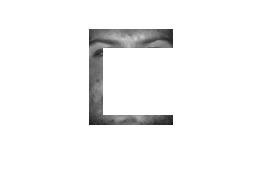

% Make corrupted block biggest!
block_missing_images = [];
for c = test_set_indexes(1:100)
blc_miss = squeeze(faces(c,:,:));
    for i=20:96-10
%     if mod(i, 96) == 0
        for j = 15:84
            blc_miss(i,j) = 256;
        end
    end
    if c == test_set_indexes(1)
        disp("Image with corrupted block example")
        imshow(blc_miss)
    end
    block_missing_images = [block_missing_images reshape(blc_miss,height*width,1);];
end


% Testing with full images in A. No random projections, no
% scaling/downsapling!
classif_accu = [];
S = 30;

for t=1:100
%     test_img = squeeze(faces(test_set_indexes(t),:,:));
    % This is my 'Y'
    flat_test_img_1 = block_missing_images(:,t);
    flat_test_img_1 = double(flat_test_img_1);
    % I did the same for Y
    % Linear regression! Very slow!
    %x = A \ y;
    x = OMP(flat_test_img_1, A, S);
    
    % Calculate residuals for each class. Pick lowest (unless above a
    % certain threshold)
    residual_for_class = [];
    for class = 1:38
        residual_for_class = [residual_for_class norm(flat_test_img_1 - A(:, labels_for_training_set' == class) * x(labels_for_training_set' == class),2)];
    end
    
    [resid cls_pick] = min(residual_for_class);
    % If min residual is very high, then the image most probably hasn't been seen before!
    if resid > 9500
        cls_pick = -1;
    end
    true_class = true_class_for_missing_block(t);
    classif_accu = [classif_accu; cls_pick, true_class];
end

correct_preds = 0;
for a=1:length(classif_accu)
    if classif_accu(a,1) == classif_accu(a,2)
        correct_preds = correct_preds + 1;
    end
end
disp("OMP - S="+S+", full dict. A. Number of correct predictions: "+ correct_preds +" / " + 100)

OMP - S=30, full dict. A. Number of correct predictions: 2 / 100


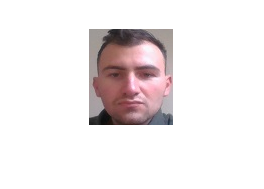

% Selfies testing!
ariel1 = imread("WIN_20210322_11_52_10_Pro_resize.jpg");
ariel2 = imread("WIN_20210322_11_52_11_Pro_resize.jpg");
ariel3 = imread("WIN_20210322_11_52_12_Pro_resize.jpg");
ariel4 = imread("WIN_20210322_11_52_14_Pro_resize.jpg");
imshow(ariel1);

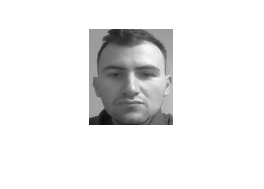


ariel1 = rgb2gray(ariel1);
ariel2 = rgb2gray(ariel2);
ariel3 = rgb2gray(ariel3);
ariel4 = rgb2gray(ariel4);
imshow(ariel1);

size(ariel1)

ans =     96    84



classif_accu = [];
S = 30;
% Solve using much faster OMP!
flat_ariel_1 = double(reshape(ariel1,height*width,1));
flat_ariel_2 = double(reshape(ariel2,height*width,1));
flat_ariel_3 = double(reshape(ariel3,height*width,1));
flat_ariel_4 = double(reshape(ariel4,height*width,1));
% Linear regression! Very slow!
%x = A \ y;
ariel_selfies = [flat_ariel_1, flat_ariel_2, flat_ariel_3, flat_ariel_4];
for j = 1:4
    flat_test_img_1 = ariel_selfies(:,j);
    x = OMP(flat_test_img_1, A, S);
    %[m chosen_img_index] = max(x);
    % Find residuals for each. zero out residuals for classes locally
    residual_for_class = [];
    for class = 1:38
        residual_for_class = [residual_for_class norm(flat_test_img_1 - A(:, labels_for_training_set' == class) * x(labels_for_training_set' == class),2)];
    end
    % if t == 1
    %     disp("Residual plot for first test image")
    %     bar(residual_for_class)
    % end
    [resid cls_pick] = min(residual_for_class);
    % If min residual is very high, then the image most probably isnt in
    % the database!
    if resid > 5500
        cls_pick = -1;
    end
    classif_accu = [classif_accu cls_pick];
end

disp("I am not in the database, so the algorithm should return Class -1: Image not found!")

I am not in the database, so the algorithm should return Class -1: Image not found!


classif_accu

classif_accu =     -1    -1    -1    -1


function [s,amplitudes,innerprod] = ForErrorProposedv0(x, dict, D, dictTx, natom, tolerance)
% Proposed OMP Implementation (v0).
% The code is obtained by modifying the relevant code in [1].
%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%
% INPUTS
% x        - input signal
% dict     - dictionary (with unit norm columns)
% D        - dictionary Gramian
% dictTx    - dict'*x
% natom    - stopping crit. 1: max number of iterations
% tolerance - stopping crit. 2: minimum norm residual
%
%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%
% OUTPUTS
% s  - solution to x = dict*s
%
%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%
x = x(:);
% initialization
residual = x;
normx2 = x'*x;
normtol2 = tolerance*normx2;
normr2 = normx2;
dictsize = size(dict,2);
L = zeros(natom,natom);
gamma = zeros(natom,1);
% find initial projections
projections = dictTx;
F=eye(natom);
a_F = zeros(natom,1);
temp_F_k_k = 0;
innerprod{1}=projections(:);
k = 1;
D_mybest = zeros(size(D,1),natom);
s = zeros(dictsize,1);
while normr2 > normtol2 && k <= natom
   [alpha,maxindex] = max(projections.^2);
   newgam = maxindex(1);
   gamma(k) = newgam;
   if k==1
      D_mybest(:,1) = D(:,newgam);
      a_F(1)= projections(newgam);
      projections = projections -D_mybest(:,1)*a_F(1);
      normr2 = normr2 -a_F(1)^2;
   else
      temp_F_k_k =sqrt(1/(1- sum(D_mybest(newgam,:).^2)));
      F(:,k)=-temp_F_k_k*(F*D_mybest(newgam,:).');
      F(k,k)=temp_F_k_k;
      D_mybest(:,k)=temp_F_k_k*(D(:,newgam)-D_mybest*D_mybest(newgam,:).');
      a_F(k)=temp_F_k_k*projections(newgam);
      projections = projections -D_mybest(:,k)*a_F(k);
      normr2 = normr2 -a_F(k)^2;
   end
  amplitudes{k}=zeros(dictsize,1);
  amplitudes{k}(gamma(1:k))=F(1:k,1:k)*a_F(1:k);
   k = k + 1;
  innerprod{k}=projections(:);
end
s(gamma(1:(k-1)))=F(1:(k-1),1:(k-1))*a_F(1:(k-1));
end


function [s,amplitudes,innerprod] = ForErrorProposedv1(x, dict, D, dictTx, natom, tolerance)
% Proposed Memory-Saving version 1.
% The code is obtained by modifying the relevant code in [1].
%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%
% INPUTS
% x        - input signal
% dict     - dictionary (with unit norm columns)
% D        - dictionary Gramian
% dictTx    - dict'*x
% natom    - stopping crit. 1: max number of iterations
% tolerance - stopping crit. 2: minimum norm residual
%
%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%
% OUTPUTS
% s  - solution to x = dict*s
%
%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%
x = x(:);
% initialization
residual = x;
normx2 = x'*x;
normtol2 = tolerance*normx2;
normr2 = normx2;
dictsize = size(dict,2);
L = zeros(natom,natom);
gamma = zeros(natom,1);
% find initial projections
projections = dictTx;
F=eye(natom);
a_F = zeros(natom,1);
temp_F_k_k = 0;
innerprod{1}=projections(:);
k = 1;
s = zeros(dictsize,1);
while normr2 > normtol2 && k <= natom
   [alpha,maxindex] = max(projections.^2);
   newgam = maxindex(1);
   gamma(k) = newgam;
   if k==1
      a_F(1)= projections(newgam);
      projections = projections -D(:,newgam)*a_F(1);
      normr2 = normr2 -a_F(1)^2;
   else
      s_k_minus_1 = D(gamma(1:k-1),newgam);
      c_k_minus_1 = F(1:k-1,1:k-1)'*s_k_minus_1;
      temp_F_k_k =sqrt(1/(1- sum(c_k_minus_1.^2)));
      F(1:k-1,k)=-temp_F_k_k*(F(1:k-1,1:k-1)*c_k_minus_1);
      F(k,k)=temp_F_k_k;
      a_F(k)=temp_F_k_k*projections(newgam);
      projections = projections -D(:,gamma(1:k))*(F(1:k,k)*a_F(k));
      normr2 = normr2 -a_F(k)^2;
   end
  amplitudes{k}=zeros(dictsize,1);
  amplitudes{k}(gamma(1:k))=F(1:k,1:k)*a_F(1:k);
   k = k + 1;
  innerprod{k}=projections(:);
end
s(gamma(1:(k-1)))=F(1:(k-1),1:(k-1))*a_F(1:(k-1));
end


function [s,amplitudes,innerprod] = ForErrorProposedv2(x, dict, D, dictTx, natom, tolerance)
% Proposed Memory-Saving version 2.
% The code is obtained by modifying the relevant code in [1].
%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%
% INPUTS
% x        - input signal
% dict     - dictionary (with unit norm columns)
% D        - dictionary Gramian
% dictTx    - dict'*x
% natom    - stopping crit. 1: max number of iterations
% tolerance - stopping crit. 2: minimum norm residual
%
%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%
% OUTPUTS
% s  - solution to x = dict*s
%
%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%

x = x(:);
% initialization
residual = x;
normx2 = x'*x;
normtol2 = tolerance*normx2;
normr2 = normx2;
dictsize = size(dict,2);
L = zeros(natom,natom);
gamma = zeros(natom,1);
% find initial projections
projections = dictTx;
F=eye(natom);
a_F = zeros(natom,1);
temp_F_k_k = 0;
innerprod{1}=projections(:);
k = 1;
D_mybest = zeros(dictsize,natom);
temp_D_row = zeros(natom,1);
E = zeros(size(dict,1),natom);
s = zeros(dictsize,1);
while normr2 > normtol2 && k <= natom
 [alpha,maxindex] = max(projections.^2);
 newgam = maxindex(1);
 gamma(k) = newgam;
 if k==1
   D_mybest(:,1) = dict.'*dict(:,newgam);
   E(:,1)=dict(:,newgam);
   a_F(1)= projections(newgam);
  projections = projections -D_mybest(:,1)*a_F(1);
   normr2 = normr2 -a_F(1)^2;
 else
temp_D_row = D_mybest(newgam,:).';
temp_F_k_k =sqrt(1/(1- sum(temp_D_row.^2)));
F(:,k)=-temp_F_k_k*(F*temp_D_row);
F(k,k)=temp_F_k_k;
 E(:,k)=temp_F_k_k*(dict(:,newgam)-E*temp_D_row);
 D_mybest(:,k)=dict.'*E(:,k);
   a_F(k)=temp_F_k_k*projections(newgam);
projections = projections -D_mybest(:,k)*a_F(k);
  normr2 = normr2 -a_F(k)^2;
 end
   amplitudes{k}=zeros(dictsize,1);
  amplitudes{k}(gamma(1:k))=F(1:k,1:k)*a_F(1:k);
 k = k + 1;
  innerprod{k}=projections(:);
end
s(gamma(1:(k-1)))=F(1:(k-1),1:(k-1))*a_F(1:(k-1));
end

 

 function [s,amplitudes,innerprod] = ForErrorProposedv3(x, dict, D, dictTx, natom, tolerance)
% Proposed Memory-Saving version 3.
% The code is obtained by modifying the relevant code in [1].
%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%
% INPUTS
% x        - input signal
% dict     - dictionary (with unit norm columns)
% D        - dictionary Gramian
% dictTx    - dict'*x
% natom    - stopping crit. 1: max number of iterations
% tolerance - stopping crit. 2: minimum norm residual
%
%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%
% OUTPUTS
% s  - solution to x = dict*s
%
%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%

x = x(:);
% initialization
residual = x;
normx2 = x'*x;
normtol2 = tolerance*normx2;
normr2 = normx2;
dictsize = size(dict,2);
L = zeros(natom,natom);
gamma = zeros(natom,1);
% find initial projections
projections = dictTx;

F=eye(natom);
a_F = zeros(natom,1);
temp_F_k_k = 0;
innerprod{1}=projections(:);
k = 1;
temp_D_row = zeros(natom,1);
E = zeros(size(dict,1),natom);
s = zeros(dictsize,1);
while normr2 > normtol2 && k <= natom
 [alpha,maxindex] = max(projections.^2);
 newgam = maxindex(1);
 gamma(k) = newgam;
 if k==1
   E(:,1)=dict(:,newgam);
   a_F(1)= projections(newgam);
projections = projections -dict.'*(E(:,1)*a_F(1));
   normr2 = normr2 -a_F(1)^2;
 else
temp_D_row = (dict(:,newgam).'*E).';
temp_F_k_k =sqrt(1/(1- sum(temp_D_row.^2)));
F(:,k)=-temp_F_k_k*(F*temp_D_row);
F(k,k)=temp_F_k_k;
 E(:,k)=temp_F_k_k*(dict(:,newgam)-E*temp_D_row);
   a_F(k)=temp_F_k_k*projections(newgam);
projections = projections -dict.'*(E(:,k)*a_F(k));
  normr2 = normr2 -a_F(k)^2;
 end
   amplitudes{k}=zeros(dictsize,1);
  amplitudes{k}(gamma(1:k))=F(1:k,1:k)*a_F(1:k);
 k = k + 1;
  innerprod{k}=projections(:);
end
s(gamma(1:(k-1)))=F(1:(k-1),1:(k-1))*a_F(1:(k-1));
 end

 
 function [s,amplitudes,innerprod] = ForErrorProposedv4(x, dict, D, dictTx, natom, tolerance)
% Proposed Memory-Saving version 4.
% The code is obtained by modifying the relevant code in [1].
%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%
% INPUTS
% x        - input signal
% dict     - dictionary (with unit norm columns)
% D        - dictionary Gramian
% dictTx    - dict'*x
% natom    - stopping crit. 1: max number of iterations
% tolerance - stopping crit. 2: minimum norm residual
%
%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%
% OUTPUTS
% s  - solution to x = dict*s
%
%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%=%

x = x(:);
% initialization
residual = x;
normx2 = x'*x;
normtol2 = tolerance*normx2;
normr2 = normx2;
dictsize = size(dict,2);
L = zeros(natom,natom);
gamma = zeros(natom,1);
% find initial projections
projections = dictTx;

F=eye(natom);
a_F = zeros(natom,1);
temp_F_k_k = 0;
innerprod{1}=projections(:);
k = 1;
temp_D_row = zeros(natom,1);
s = zeros(dictsize,1);
while normr2 > normtol2 && k <= natom
 [alpha,maxindex] = max(projections.^2);
 newgam = maxindex(1);
 gamma(k) = newgam;
 if k==1
   a_F(1)= projections(newgam);
projections = projections -dict.'*(dict(:,gamma)*(F(1,1)*a_F(1)));
   normr2 = normr2 -a_F(1)^2;
 else   
g_lamda_k = dict(:,newgam).'*dict(:,newgam);
s_k_minus_1 = dict(:,gamma(1:k-1)).'*dict(:,newgam);
c_k_minus_1 = F(1:k-1,1:k-1)'*s_k_minus_1;
temp_F_k_k =sqrt(1/(1- sum(c_k_minus_1.^2)));
F(:,k)=-temp_F_k_k*(F*c_k_minus_1);
F(k,k)=temp_F_k_k;
   a_F(k)=temp_F_k_k*projections(newgam);
projections = projections -dict.'*(dict(:,gamma)*(F(1:k,k)*a_F(k)));
  normr2 = normr2 -a_F(k)^2;
 end
   amplitudes{k}=zeros(dictsize,1);
  amplitudes{k}(gamma(1:k))=F(1:k,1:k)*a_F(1:k);
 k = k + 1;
  innerprod{k}=projections(:);
end
s(gamma(1:(k-1)))=F(1:(k-1),1:(k-1))*a_F(1:(k-1));
end

% Original Naive OMP
function x = OMP(y, Phi, K)
% Othogonal matching pursuit of Tropp et Gilbert
% y : data
% Phi : sensing matrix
% K : sparsity
% SYM March 13 2013
[~,N] = size(Phi);
x = zeros(1,N);
S = []; % positions indexes of components of s
res = y; % first residual
PhiS = []; % Matrix of the columns used to represent y
for t=1:K;
    [~,j]=max(abs(Phi'*res));
    S = [S j];
    PhiS = [PhiS Phi(:,j)];
    x_est = pinv(PhiS)*y;
    res = y- PhiS*x_est;
    x(S) = x_est;
end;
x = x';
end
